# Generating Sounds and Testing Cross Correlation 

#### By El Mehdi BENSEDDIK

## I - Creating Sinus Pulse

clear                                  % Clear all data stored in variables
Amplitude = 0.1;                         % 1V     
samplingFrequency = 48000;             % 48 KHz
frequency = 2e+3;                     % 2 KHz
samples = 48;                           % Buffer size
duration = ((samples-1)/samplingFrequency);    % ~ 21.3 ms 
t = 0:1/samplingFrequency:duration;    % Time Vector

sinusPulse = Amplitude*sin(2*pi*frequency*t); % sinusPulse(t) = 1*sin(2*pi*1000*t)

#### Shifting the pure sinus signal

shiftedSinus(samples) = 0;
shiftedSinus(end/2+1:end) = sinusPulse(1:end/2);

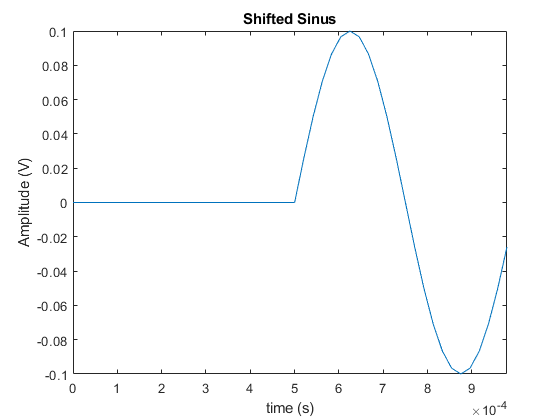

plot(t,shiftedSinus); 
title('Shifted Sinus')   
ylabel('Amplitude (V)')
xlabel('time (s)')
xlim([0 max(t)])

#### Convert signals into Q8 form

inputSinus = int16((sinusPulse)*(2^8));
shiftedSinus = int16((shiftedSinus)*(2^8));

### I- 1- Plotting Sinus

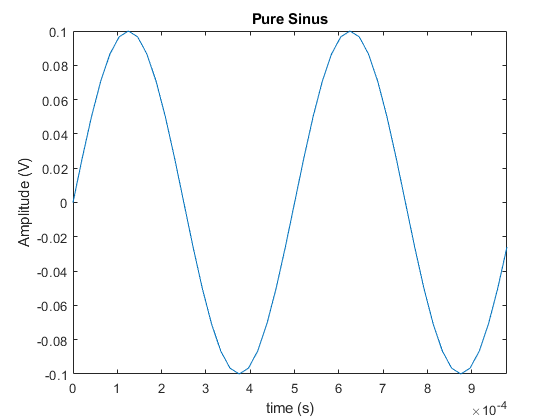

plot(t,sinusPulse); 
title('Pure Sinus')   
ylabel('Amplitude (V)')
xlabel('time (s)')
xlim([0 max(t)])

csvwrite('pureSinus.csv',inputSinus)
csvwrite('shiftedSinus.csv',shiftedSinus)

#### Cross Correlation

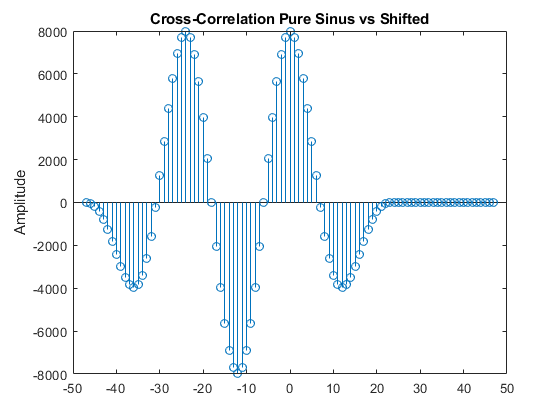

a = 1:20;
b = 19:-1:0;
[acor, lag] = xcorr(inputSinus, shiftedSinus);
stem(lag,acor)
ylabel('Amplitude')
title('Cross-Correlation Pure Sinus vs Shifted')

### I- 3- Listening to the tone

% sound(sinusPulse)